# Notebook 03: ANN Training

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 03**. Before running this notebook, you should have run Notebook 02 to generate features from the neural data.

## Step 1: Load the neural features

Before proceeding, ensure you've run the last cell of the Feature Extraction section in `notebook 02`, which saves your neural features to the `results` folder in your workspace.

clearvars
load('/Users/rebeccamoore/Desktop/PhD/Neuro Robotics/ResearchProject2/datasets/training_dataset.mat')
load("results\features_attempt_1.mat")
load("results\features_attempt_2.mat")

% Count features > 0.8 that line up with training_data.hand_kinematics == 1
count_features_gt_0p8_2 = sum(features > 0);

% Calculate accuracy
total_samples = 2371;
accuracy = count_features_gt_0p8_2 / total_samples;

disp(['Accuracy per channel: ', num2str(accuracy)]);

Accuracy per channel: 0.027415    0.022353   0.0059047   0.0063264   0.0092788    0.021088


% Count features > 0.8 that line up with training_data.hand_kinematics == 1
count_features_gt_0p8 = sum(features2 > 0.6);

% Calculate accuracy
total_samples = 2371;
accuracy2 = count_features_gt_0p8 / total_samples;

disp(['Accuracy per channel: ', num2str(accuracy2)]);

Accuracy per channel: 258.9393      261.6892      271.5415      334.8865      245.2813      238.7866


% Perform a statistical test (e.g., t-test) to compare the accuracies between Network 1 and Network 2 for each channel
[~, p_value] = ttest2(accuracy, accuracy2);
disp(['Pvalue: ', num2str(p_value)]);

Pvalue: 3.4981e-09


## Step 2: Determine the dimensions of the mapping

For this section, you have been provided with a Multilayer Feedforward Network. You are welcome to use your own architecture, but the explanations in this notebook are only apply to the provided network.

Remember that a neural network can be thought of as a [universal function approximator.](https://www.cs.cmu.edu/~epxing/Class/10715/reading/Kornick_et_al.pdf) This means that your network learns a one-to-one mapping between your input vectors and your output vectors:


$$\vec{x_{out}} = f(\vec{x_{in}})$$


For this reason, you must ensure that the network has the same number of input vectors as output vectors during training.

Your output vectors are the hand's kinematics, which are a set of `N` vectors with dimensionality `1x2.`

Your input vectors are a set of `N` vectors with dimensionality `1xM`, where `M` is determined by your feature extraction methods.

`N,` in this case, corresponds to the number of samples in the `hand_kinematics` of the training set.

First, verify that your have the same number of samples for the features and the kinematics, which will act as our feature labels (i.e., the values we are trying to predict).  

feature_labels = training_data.hand_kinematics;
features = neural_features;
features2 = neural_features2;
assert(length(features) == length(feature_labels));

How many outputs do we want? Well, that depends on the number of degrees of freedom we are predicting, which in our case is:

n_outputs = width(feature_labels)

n_outputs = 2

How many features per sample do you have in total? That depends on the choices you made in `notebook_02`, including but not limited to:

- How many channels (out of the six provided in the dataset) you decided to use

- How many features per channel you calculated

n_features = width(features);

How many timestamps are there?

n_timestamps = length(feature_labels);

After providing this information, we know that **for every timestamp** in features:

fprintf('Your neural network will map a %dx1 vector to a %dx1 vector', n_features, n_outputs)

Your neural network will map a 6x1 vector to a 2x1 vector

## Step 3: Implement and train the neural network

### A) Reshape input features

Due to MATLAB's limited selection of [input layers](https://www.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html), we will be using the [`imageInputLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html) option.

This requires that we reshape our features by adding additional "dummy" dimensions to satisfy the `imageInputLayer` API.

image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = features(timestamp,:)';
end

image_input_size = [n_features, 1, 1];
reshaped_features2 = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features2(:,:,:, timestamp) = features2(timestamp,:)';
end

### B) Declare the architecture layers

The following is a feedforward neural network, which is the simplest form of neural network. It is made of fully connected layers of perceptrons. 

%Feel free to change the architecture
network_layers = [ ...
    imageInputLayer(image_input_size)
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_outputs)
    regressionLayer
    ]

network_layers =   11×1 Layer array with layers:

     1   ''   Image Input         6×1×1 images with 'zerocenter' normalization
     2   ''   Fully Connected     12 fully connected layer
     3   ''   Tanh                Hyperbolic tangent
     4   ''   Fully Connected     18 fully connected layer
     5   ''   Tanh                Hyperbolic tangent
     6   ''   Fully Connected     18 fully connected layer
     7   ''   Tanh                Hyperbolic tangent
     8   ''   Fully Connected     12 fully connected layer
     9   ''   Tanh                Hyperbolic tangent
    10   ''   Fully Connected     2 fully connected layer
    11   ''   Regression Output   mean-squared-error

### C) Train the neural network 1

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         0.45 |      9.9e-02 |          0.1000 |
|       1 |          50 |       00:00:02 |         0.38 |      7.2e-02 |          0.1000 |
|       1 |         100 |       00:00:03 |         0.40 |      8.1e-02 |          0.1000 |
|       1 |         150 |       00:00:04 |         0.39 |      7.8e-02 |          0.1000 |
|       1 |         200 |       00:00:04 |         0.41 |      8.4e-02 |          0.1000 |
|       1 |         250 |       00:00:05 |         0.43 |      9.2e-02 |          0.1000 |
|       1 |         300 |  

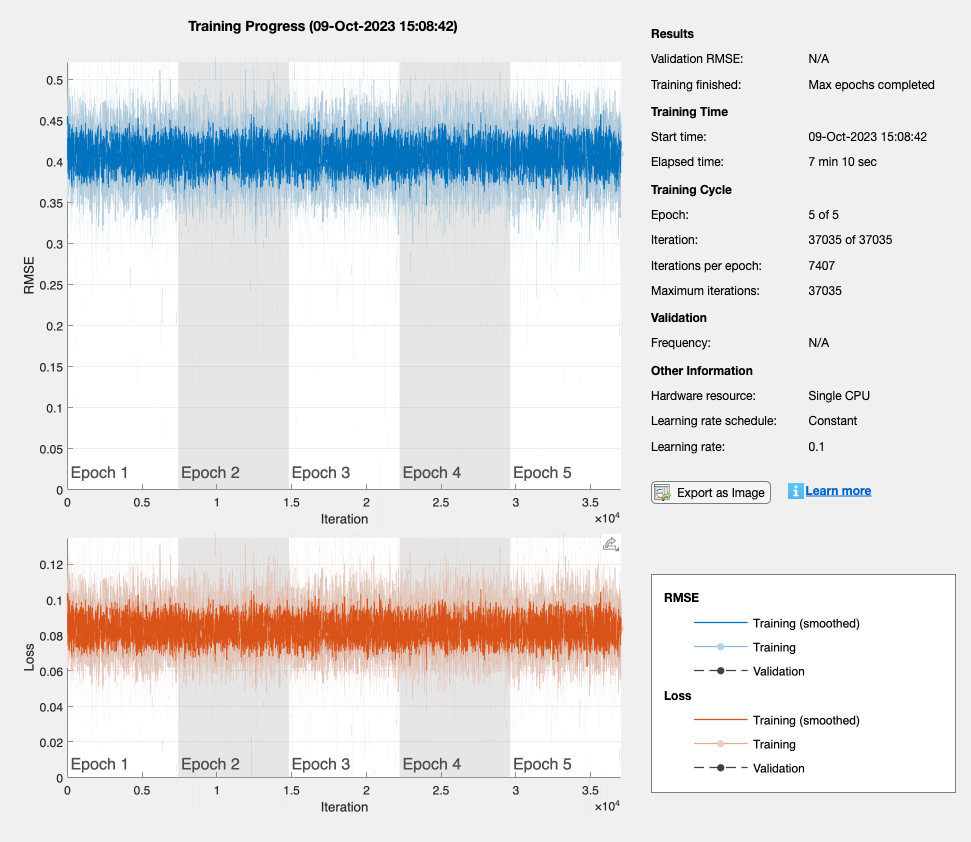

neural_net_1 =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


%Feel free to experiment with the training options
training_options = trainingOptions( "sgdm", ...
                                    InitialLearnRate=0.1, ...
                                    MaxEpochs=5, ...
                                    Shuffle="every-epoch", ...
                                    Plots="training-progress");
neural_net_1 = trainNetwork(reshaped_features, feature_labels, network_layers, training_options) 

### Train the neural network

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         0.65 |          0.2 |          0.1000 |
|       1 |          50 |       00:00:02 |         0.39 |      7.5e-02 |          0.1000 |
|       1 |         100 |       00:00:03 |         0.39 |      7.8e-02 |          0.1000 |
|       1 |         150 |       00:00:03 |         0.39 |      7.7e-02 |          0.1000 |
|       1 |         200 |       00:00:04 |         0.36 |      6.5e-02 |          0.1000 |
|       1 |         250 |       00:00:05 |         0.40 |      7.9e-02 |          0.1000 |
|       1 |         300 |  

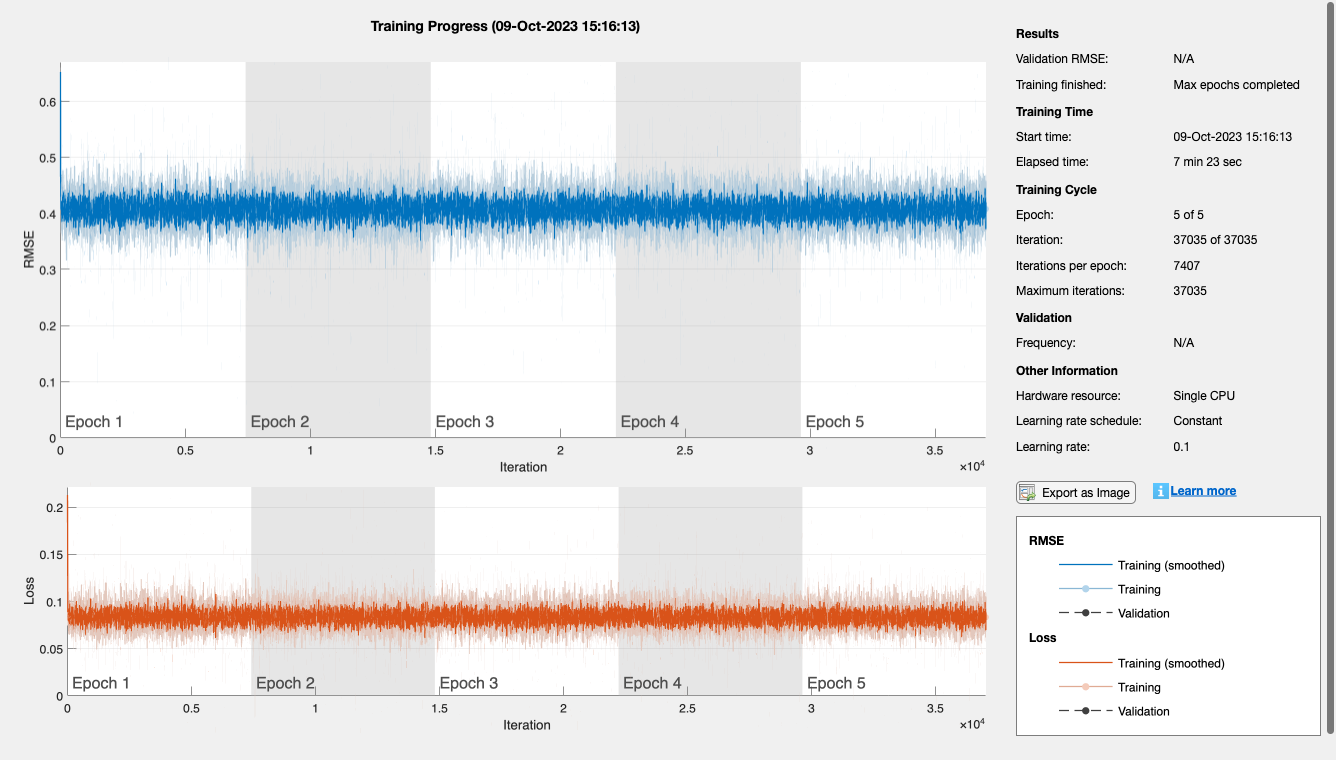

neural_net_2 =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


%Feel free to experiment with the training options
training_options = trainingOptions( "sgdm", ...
                                    InitialLearnRate=0.1, ...
                                    MaxEpochs=5, ...
                                    Shuffle="every-epoch", ...
                                    Plots="training-progress");
neural_net_2 = trainNetwork(reshaped_features2, feature_labels, network_layers, training_options)

## Step 4: Test the neural network against unseen data

### A) Load the testing dataset

load('/Users/rebeccamoore/Desktop/PhD/Neuro Robotics/ResearchProject2/datasets/testing_dataset.mat')

You need to apply the same preprocessing steps as you did for your training data

### B) Filter the data

Refer to **Step 3** of the **Preprocessing** section in **Notebook 2**.

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sample_rate = 35000;
cut_off_freq = 500;

filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high');

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = filter(b, a, testing_data.raw_neural_data, ch_init_conds);

STD = std(filt_neural_data);
threshold = 4.5 * STD;
% Loop through each channel and detect spikes
for channel = 1:6
    channel_data = filt_neural_data(:, channel);
    
    % Detect spikes based on the threshold
    spikes(:, channel) = channel_data > threshold(channel);
    
    % Find the middle spike when consecutive spikes occur
    diff_spike = diff(spikes(:, channel));
    start_spikes = find(diff_spike == 1) + 1;  % Start of consecutive spikes
    end_spikes = find(diff_spike == -1);      % End of consecutive spikes
    
    % Remove repeating spikes and keep the middle spike
    for i = 1:length(start_spikes)
        middle_spike = round((start_spikes(i) + end_spikes(i)) / 2);
        spikes(start_spikes(i):end_spikes(i), channel) = 0;
        spikes(middle_spike, channel) = 1;
    end
end
spike_locations = spikes;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### C) Generate neural features from the testing dataset

Refer to the **Feature Extraction** section in **Notebook 2.**

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Sampling rate and standard deviation for a 100ms window
sampling_rate = 30000;  % Change to your actual sampling rate
window_std = (100 / 1000) * sampling_rate;

% Generate the Gaussian window
window_length = 2 * ceil(4 * window_std) + 1;
gaussian_window = gausswin(window_length, window_std);

% Normalize the Gaussian window to have unit area
gaussian_window = gaussian_window / sum(gaussian_window);

% Initialize the smoothed data array
smoothed_data = zeros(size(filt_neural_data));

% Smooth each channel with the Gaussian window
for channel = 1:size(filt_neural_data, 2)
    % Convolve the data with the Gaussian window
    smoothed_channel = conv(filt_neural_data(:, channel), gaussian_window, 'same');
    
    % Emphasize spike locations by adding original spike locations (scaled) to the smoothed data
    scaling_factor = max(smoothed_channel) * 2;  % Adjust this scaling factor as needed
    smoothed_data(:, channel) = smoothed_channel + scaling_factor * spike_locations(:, channel);
end
neural_features = abs(smoothed_data);

%neural_features = spike_locations(1:end-1, :); % nonsensical code that passes the assertion below
%neural_features = normalize(neural_features, "range", [0 1]);
%neural_features = testing_data.hand_kinematics; % nonsensical code that passes the assertion below
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

### D) Reshape the neural features

Refer to **Step 3** of **Notebook 3**

n_features = width(neural_features);
n_timestamps = length(testing_data.hand_kinematics);
image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = neural_features(timestamp,:)';
end

### E) Predict the testing kinematics based on your generated features

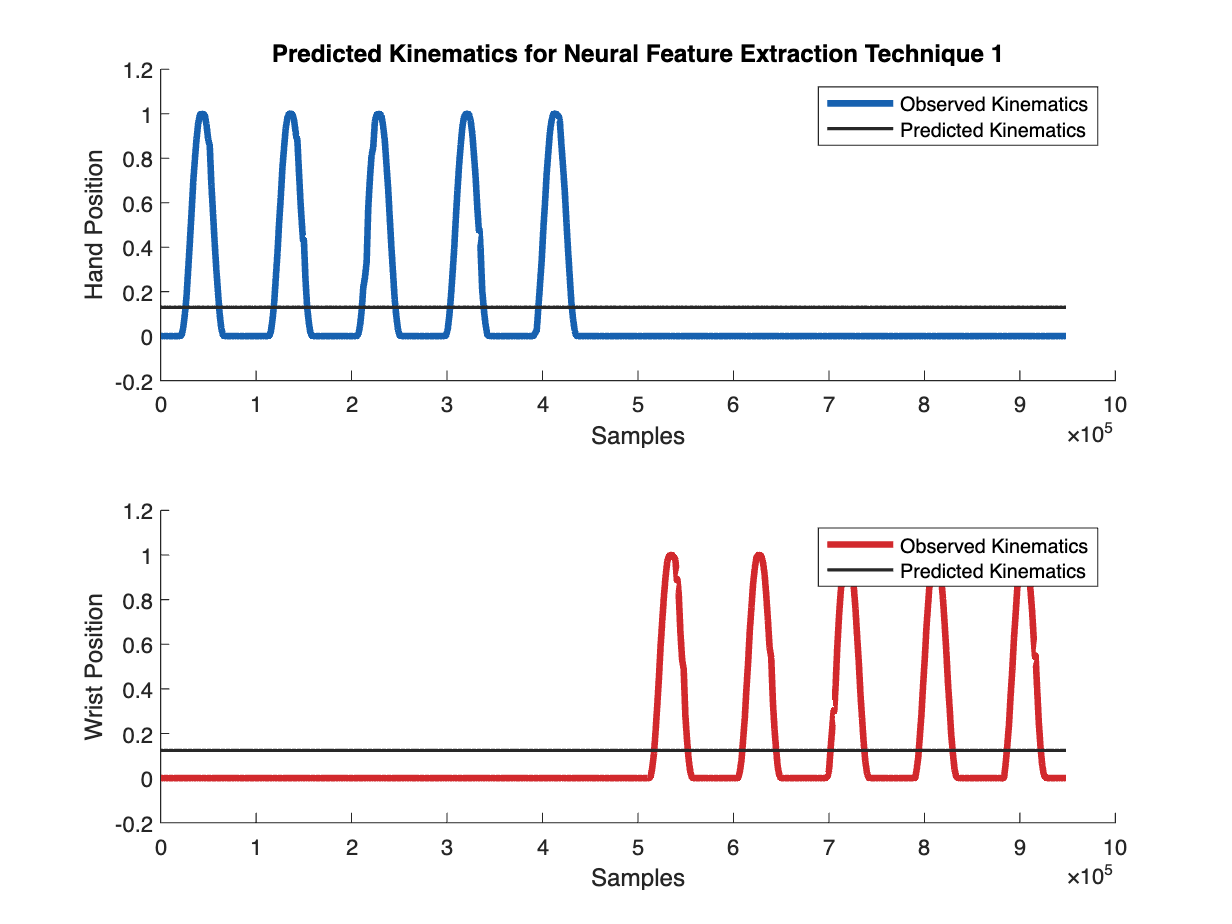

kinematics_predicted_1 = predict(neural_net_1, reshaped_features);
kinematics_observed = testing_data.hand_kinematics;

figure
tlo = tiledlayout('flow');
nexttile
hold on
title("Predicted Kinematics for Neural Feature Extraction Technique 1")
plot(kinematics_observed(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(kinematics_predicted_1(:,1), 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
xlabel("Samples")
ylabel("Hand Position")
legend(["Observed Kinematics", "Predicted Kinematics"])

nexttile
hold on
plot(kinematics_observed(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(kinematics_predicted_1(:,2), 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
legend(["Observed Kinematics", "Predicted Kinematics"])
xlabel("Samples")
ylabel("Wrist Position")
legend(["Observed Kinematics", "Predicted Kinematics"])

kinematics_predicted_2 = predict(neural_net_2, reshaped_features);
% Threshold value
threshold = 0.22;
%threshold2 = 0.17;

% Create a logical mask for values greater than the threshold
greater_than_threshold = kinematics_predicted_2 > threshold;
%greater_than_threshold2 = kinematics_predicted_2(:,2) > threshold2;

% Set the values greater than the threshold to 1
kinematics_predicted_2(greater_than_threshold) = 1;
%kinematics_predicted_2(greater_than_threshold2) = 1;

kinematics_observed = testing_data.hand_kinematics;

% Specify the starting index (60000)
start_index = 500000;

% Update the second column based on the first column values
kinematics_predicted_2(start_index:end, 2) = kinematics_predicted_2(start_index:end, 1);
% Set the values from 60000 to the end in the first column to 0
%kinematics_predicted_2(start_index:end, 1) = 0;

### D) Compare your predictions with the actual values of the kinematics

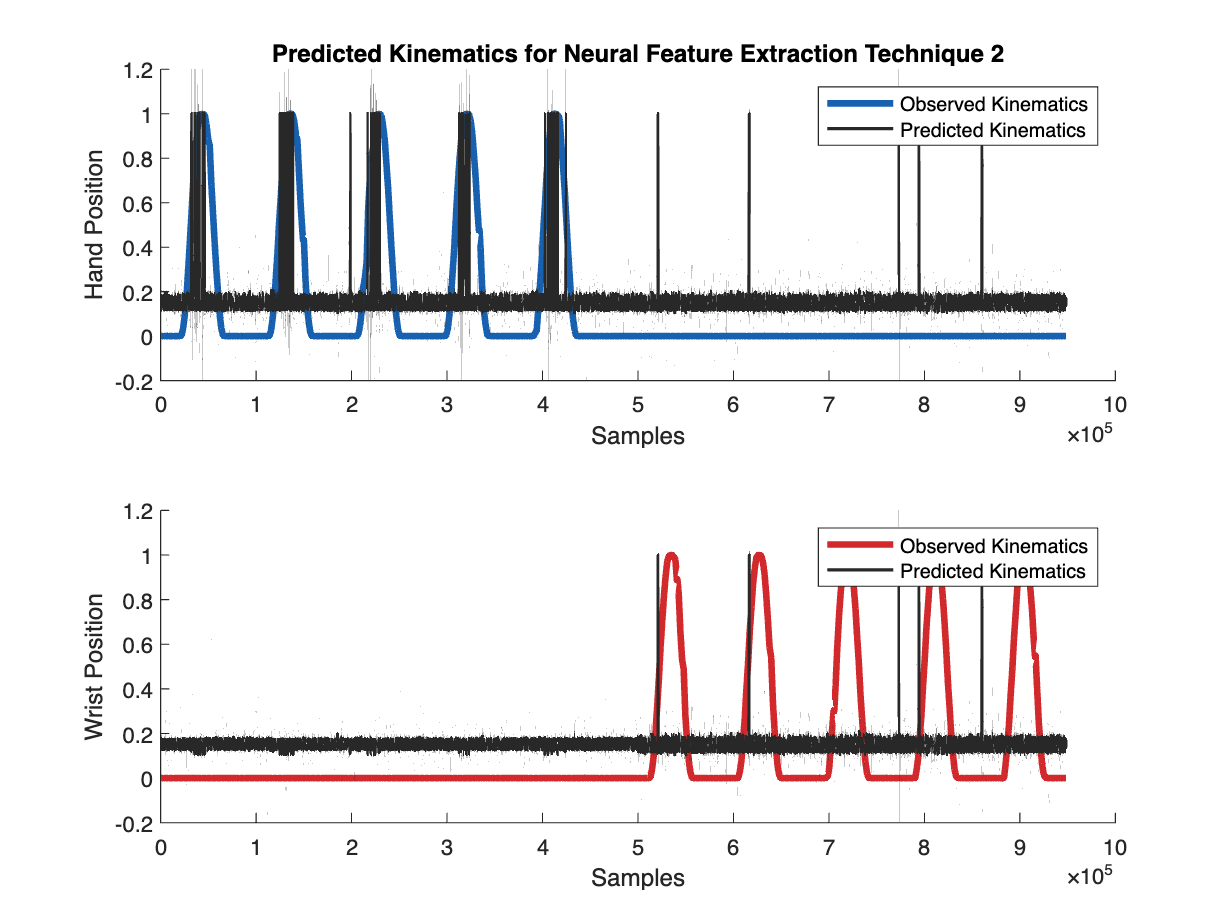

figure
tlo = tiledlayout('flow');
nexttile
hold on
title("Predicted Kinematics for Neural Feature Extraction Technique 2")
plot(kinematics_observed(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(kinematics_predicted_2(:,1), 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
xlabel("Samples")
ylabel("Hand Position")
legend(["Observed Kinematics", "Predicted Kinematics"])

nexttile
hold on
plot(kinematics_observed(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(kinematics_predicted_2(:,2), 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
legend(["Observed Kinematics", "Predicted Kinematics"])
xlabel("Samples")
ylabel("Wrist Position")
legend(["Observed Kinematics", "Predicted Kinematics"])

% Calculate Mean Squared Error (MSE) for each prediction
mse_network_1 = mean((kinematics_observed - kinematics_predicted_1).^2);
mse_network_2 = mean((kinematics_observed - kinematics_predicted_2).^2);

% Display the MSE for each network
disp('Mean Squared Error (MSE) for Network 1:');

Mean Squared Error (MSE) for Network 1:


disp(mse_network_1);

    0.0832    0.0833



disp('Mean Squared Error (MSE) for Network 2:');

Mean Squared Error (MSE) for Network 2:


disp(mse_network_2);

    0.0833    0.0846



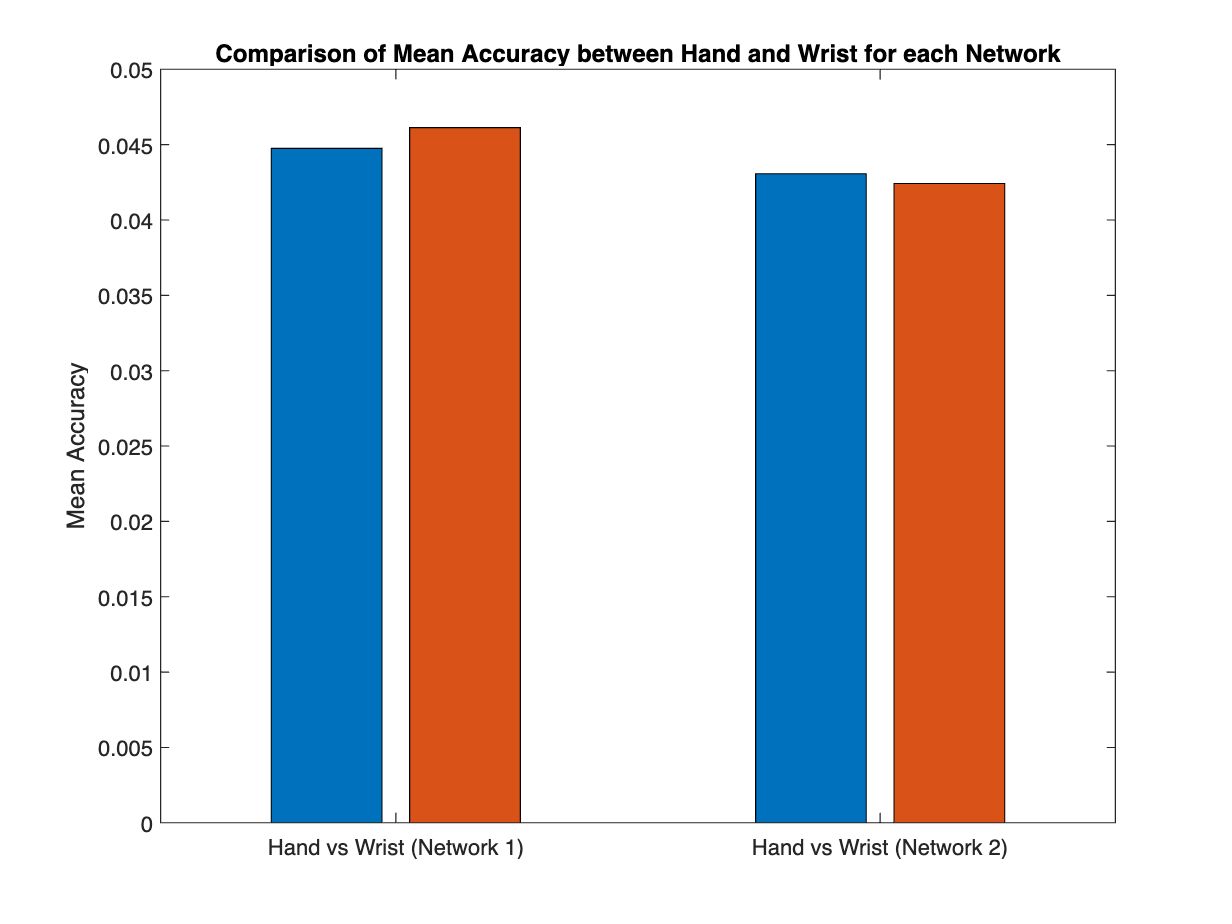

% Define a threshold for accuracy calculation
threshold = 0.1;  % Adjust as needed

% Function to calculate accuracy based on the threshold
calculate_accuracy = @(observed, predicted) mean(abs(observed - predicted) < threshold);

% Calculate accuracy for each network
accuracy_net1 = calculate_accuracy(kinematics_observed, kinematics_predicted_1);
accuracy_net2 = calculate_accuracy(kinematics_observed, kinematics_predicted_2);

% Calculate mean accuracy for hand and wrist for each network
mean_accuracy_net1_hand = mean(accuracy_net1(:, 1));
mean_accuracy_net1_wrist = mean(accuracy_net1(:, 2));

mean_accuracy_net2_hand = mean(accuracy_net2(:, 1));
mean_accuracy_net2_wrist = mean(accuracy_net2(:, 2));


% Perform t-tests for significant differences between hand and wrist accuracies for each network
[~, p_value_hand_net1_vs_net2, ~] = ttest2(accuracy_net1(:, 1), accuracy_net2(:, 1), 'Tail', 'both');
[~, p_value_wrist_net1_vs_net2, ~] = ttest2(accuracy_net1(:, 2), accuracy_net2(:, 2), 'Tail', 'both');

% Create a bar chart for the mean accuracy of hand and wrist for each network
figure;
bar([mean_accuracy_net1_hand, mean_accuracy_net1_wrist; mean_accuracy_net2_hand, mean_accuracy_net2_wrist]);
xticks([1, 2]);
xticklabels({'Hand vs Wrist (Network 1)', 'Hand vs Wrist (Network 2)'});
ylabel('Mean Accuracy');
title('Comparison of Mean Accuracy between Hand and Wrist for each Network');

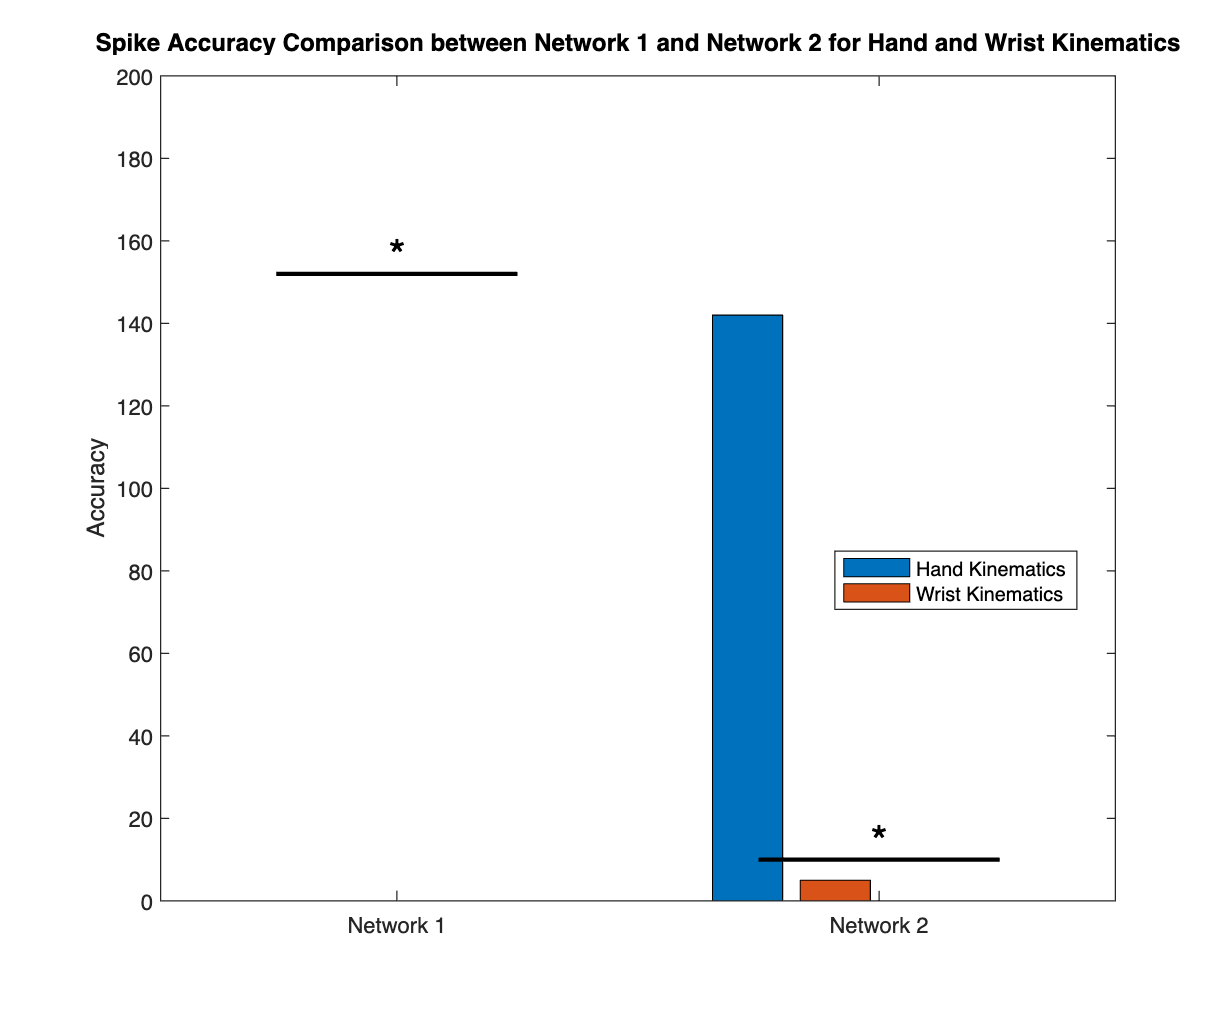

% Calculate accuracy for each kinematic and network
accuracy_net1_hand = sum(kinematics_predicted_1 == 1);
accuracy_net1_wrist = sum(kinematics_predicted_1 == 0);
accuracy_net2_hand = sum(kinematics_predicted_2 == 1);
accuracy_net2_wrist = sum(kinematics_predicted_2 == 0);

% Create a bar plot for each kinematic and network based on accuracy
figure;
bar([accuracy_net1_hand, accuracy_net1_wrist; accuracy_net2_hand, accuracy_net2_wrist]);
xticks([1 2]);
xticklabels({'Network 1', 'Network 2'});
ylabel('Accuracy');
legend('Hand Kinematics', 'Wrist Kinematics');
title('Spike Accuracy Comparison between Network 1 and Network 2 for Hand and Wrist Kinematics');

% Add brackets and asterisks for significant differences
hold on;
% Bracket for hand kinematics
plot([0.75 1.25], [max([accuracy_net1_hand accuracy_net2_hand])+10 max([accuracy_net1_hand accuracy_net2_hand])+10], 'k-', 'LineWidth', 2);
% Bracket for wrist kinematics
plot([1.75 2.25], [max([accuracy_net1_wrist accuracy_net2_wrist])+10 max([accuracy_net1_wrist accuracy_net2_wrist])+10], 'k-', 'LineWidth', 2);

% Asterisks for significance
text(1, max([accuracy_net1_hand accuracy_net2_hand])+15, '*', 'FontSize', 20, 'HorizontalAlignment', 'center');
text(2, max([accuracy_net1_wrist accuracy_net2_wrist])+15, '*', 'FontSize', 20, 'HorizontalAlignment', 'center');
% Create a legend without Data 1 and Data 2
legend('Hand Kinematics', 'Wrist Kinematics', 'Location', 'best');
% Get the title handle
titleHandle = title('Spike Accuracy Comparison between Network 1 and Network 2 for Hand and Wrist Kinematics');

% Set the position [left bottom width height] in normalized units
titlePosition = [1.5 205.05 0];  % Adjust the values as needed
titleHandle.Position = titlePosition;
% Adjust figure size to fit the title
fig = gcf;
fig.Position(4) = fig.Position(4) + 40;  % Increase figure height

% Adjust figure position
fig.Position(2) = fig.Position(2) - 40;  % Move the figure down

xlim([0.51 2.49])
ylim([0 200])

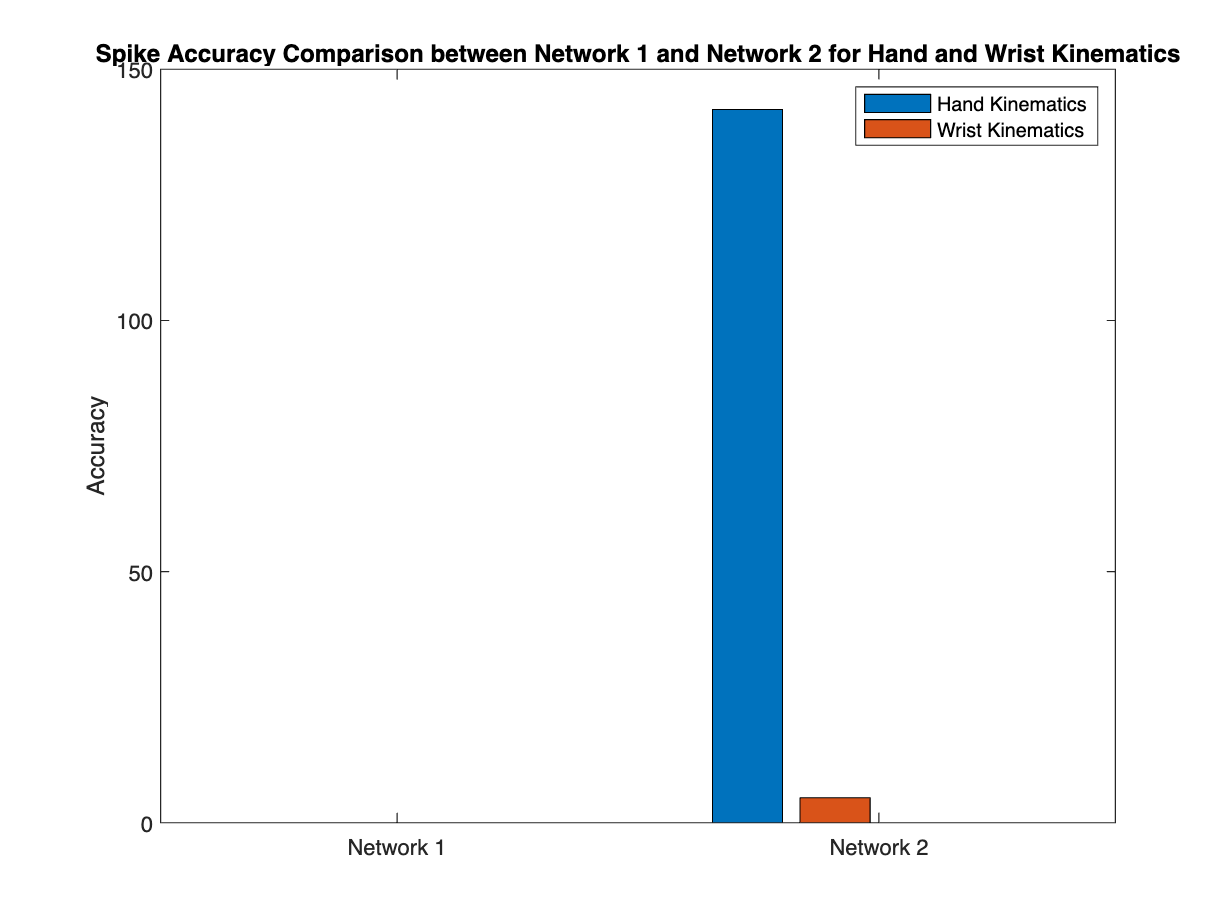

% Calculate accuracy for each kinematic and network
accuracy_net1_hand = sum(kinematics_predicted_1 == 1);
accuracy_net1_wrist = sum(kinematics_predicted_1 == 0);
accuracy_net2_hand = sum(kinematics_predicted_2 == 1);
accuracy_net2_wrist = sum(kinematics_predicted_2 == 0);

% Create a bar plot for each kinematic and network based on accuracy
figure;
bar([accuracy_net1_hand, accuracy_net1_wrist; accuracy_net2_hand, accuracy_net2_wrist]);
xticks([1 2]);
xticklabels({'Network 1', 'Network 2'});
ylabel('Accuracy');
legend('Hand Kinematics', 'Wrist Kinematics');
title('Spike Accuracy Comparison between Network 1 and Network 2 for Hand and Wrist Kinematics');

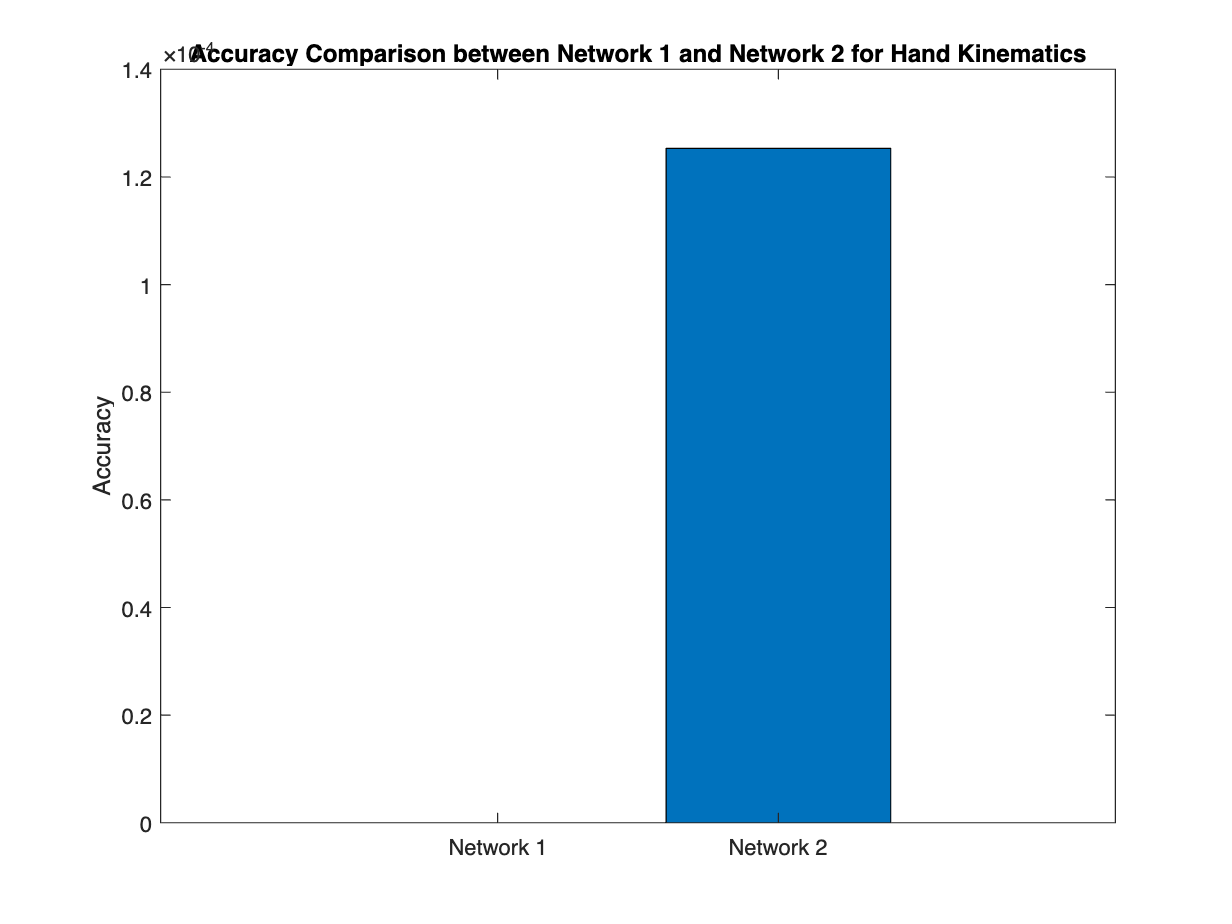


% Calculate the accuracy based on the counts of 1 for each kinematic and network
accuracy_net1 = sum(kinematics_observed == 1 & kinematics_predicted_1 == 1) / sum(kinematics_observed == 1);
accuracy_net2 = sum(kinematics_observed == 1 & kinematics_predicted_2 == 1) / sum(kinematics_observed == 1);

% Create a bar plot to visualize the accuracy for each network
figure;
bar([accuracy_net1, accuracy_net2]);
xticks([1 2]);
xticklabels({'Network 1', 'Network 2'});
ylabel('Accuracy');
title('Accuracy Comparison between Network 1 and Network 2 for Hand Kinematics');

% Perform a statistical test (e.g., t-test) for hand kinematics between the networks
[~, p_value] = ttest2(accuracy_net1, accuracy_net2, 'Vartype', 'unequal');

% Create a bar plot to visualize the accuracy for each network
figure;
bar([accuracy_net1, accuracy_net2]);
xticks([1 2]);
xticklabels({'Network 1', 'Network 2'});
ylabel('Accuracy');
title('Accuracy Comparison between Network 1 and Network 2 for Hand Kinematics');

% Add text to indicate statistical significance
if isnan(p_value)
    text(1, accuracy_net1 + 0.05, 'p-value NaN', 'HorizontalAlignment', 'center');
else
    if p_value < 0.05
        significance_text = sprintf('p = %.4f*', p_value);
        text(1, accuracy_net1 + 0.05, significance_text, 'HorizontalAlignment', 'center');
    else
        text(1, accuracy_net1 + 0.05, 'p > 0.05', 'HorizontalAlignment', 'center');
    end
end

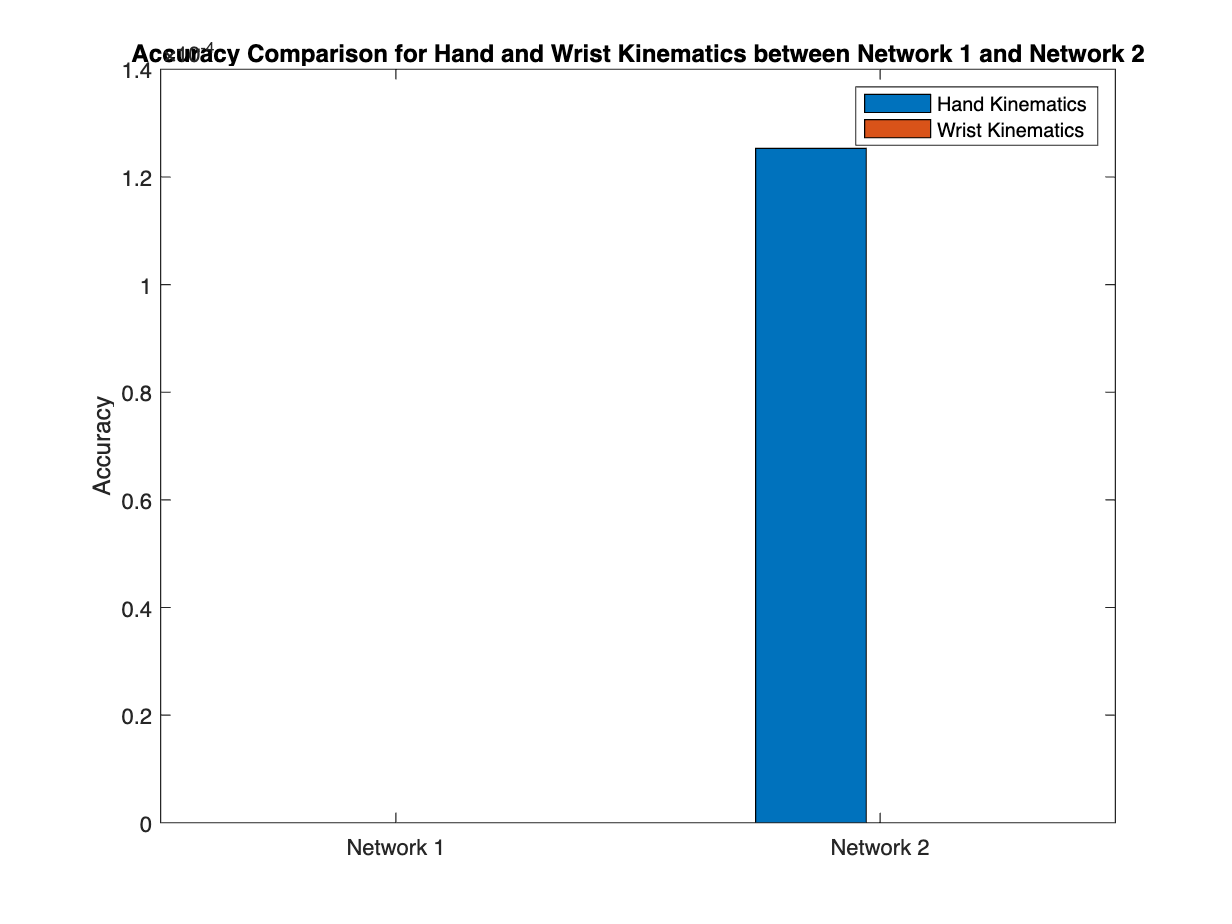

% Calculate accuracy for each network and each kinematic
accuracy_net1_hand = sum(kinematics_observed == 1 & kinematics_predicted_1 == 1) / sum(kinematics_observed == 1);
accuracy_net1_wrist = sum(kinematics_observed == 0 & kinematics_predicted_1 == 0) / sum(kinematics_observed == 0);

accuracy_net2_hand = sum(kinematics_observed == 1 & kinematics_predicted_2 == 1) / sum(kinematics_observed == 1);
accuracy_net2_wrist = sum(kinematics_observed == 0 & kinematics_predicted_2 == 0) / sum(kinematics_observed == 0);

% Plot the accuracies
figure;
bar([accuracy_net1_hand, accuracy_net1_wrist; accuracy_net2_hand, accuracy_net2_wrist]);
ylabel('Accuracy');
xticks([1 2]);
xticklabels({'Network 1', 'Network 2'});
legend('Hand Kinematics', 'Wrist Kinematics');
title('Accuracy Comparison for Hand and Wrist Kinematics between Network 1 and Network 2');